# Maximizing Solar Panel Output for a Fixed Area

In this project, our team **Solar Panel Team #3** designed a solution to identify the **optimal tilt angle** and **optimal aspect ratio** of a solar panel to deliver the **maximal energy output** given environmental constraints. Additionally this project maps the optimal energy output onto a surf plot to illustrate how energy output is dependent on tilt angle and aspect ratio. 

## MODEL 1: Maximizing Energy Output given fixed constraints

The purpose of this model was to provide a way of finding the Maximum Energy Output given fixed environmental constraints

### Objective 1: Implement the Optimization Problem

The [optimization problem](https://www.mathworks.com/help/releases/R2026a/optim/ug/problem-based-workflow.html) solves for the **Maximum Energy Output**. 

% Step 1: Define the Optimization Problem (Solar_Max). Give it a description of its purpose and solve for Maximum Value Output
    Solar_Max = optimproblem("Description","The Maximal Energy Output","ObjectiveSense","maximize");


By defining the optimization variables **Tilt Angle **(theta) and **Aspect Ratio **(r) the solver finds the highest energy output given the constraints of Tilt Angle and Aspect Ratio. 

In Model 1, the environmental **Constraints are Fixed,** based off a theoretical assumption given in the project description. 

Constraint for Tilt Angle: $0\degree \le \theta \le 90\degree$

Constraint for Aspect Ratio: $0\ldotp 5\le r\le 4$ 

% Step 2: Define Optimization Variables and set Constraints
   
    % Constrain the lowest possible tilt angle to 0 degrees and the highest to 90 degrees 
        theta = optimvar("theta","lowerbound",0, "UpperBound",90);

    % Constrain the lowest possible aspect ratio to 0.5 and highest to 4
        r = optimvar("r","lowerbound",0.5,"UpperBound", 4);


### Objective 2: Define the Objective Function

The energy function is the objective function for this optimization problem. It calculates how much energy a solar panel produces based on its **Tilt Angle (theta) **and** Aspect Ratio (r)**

 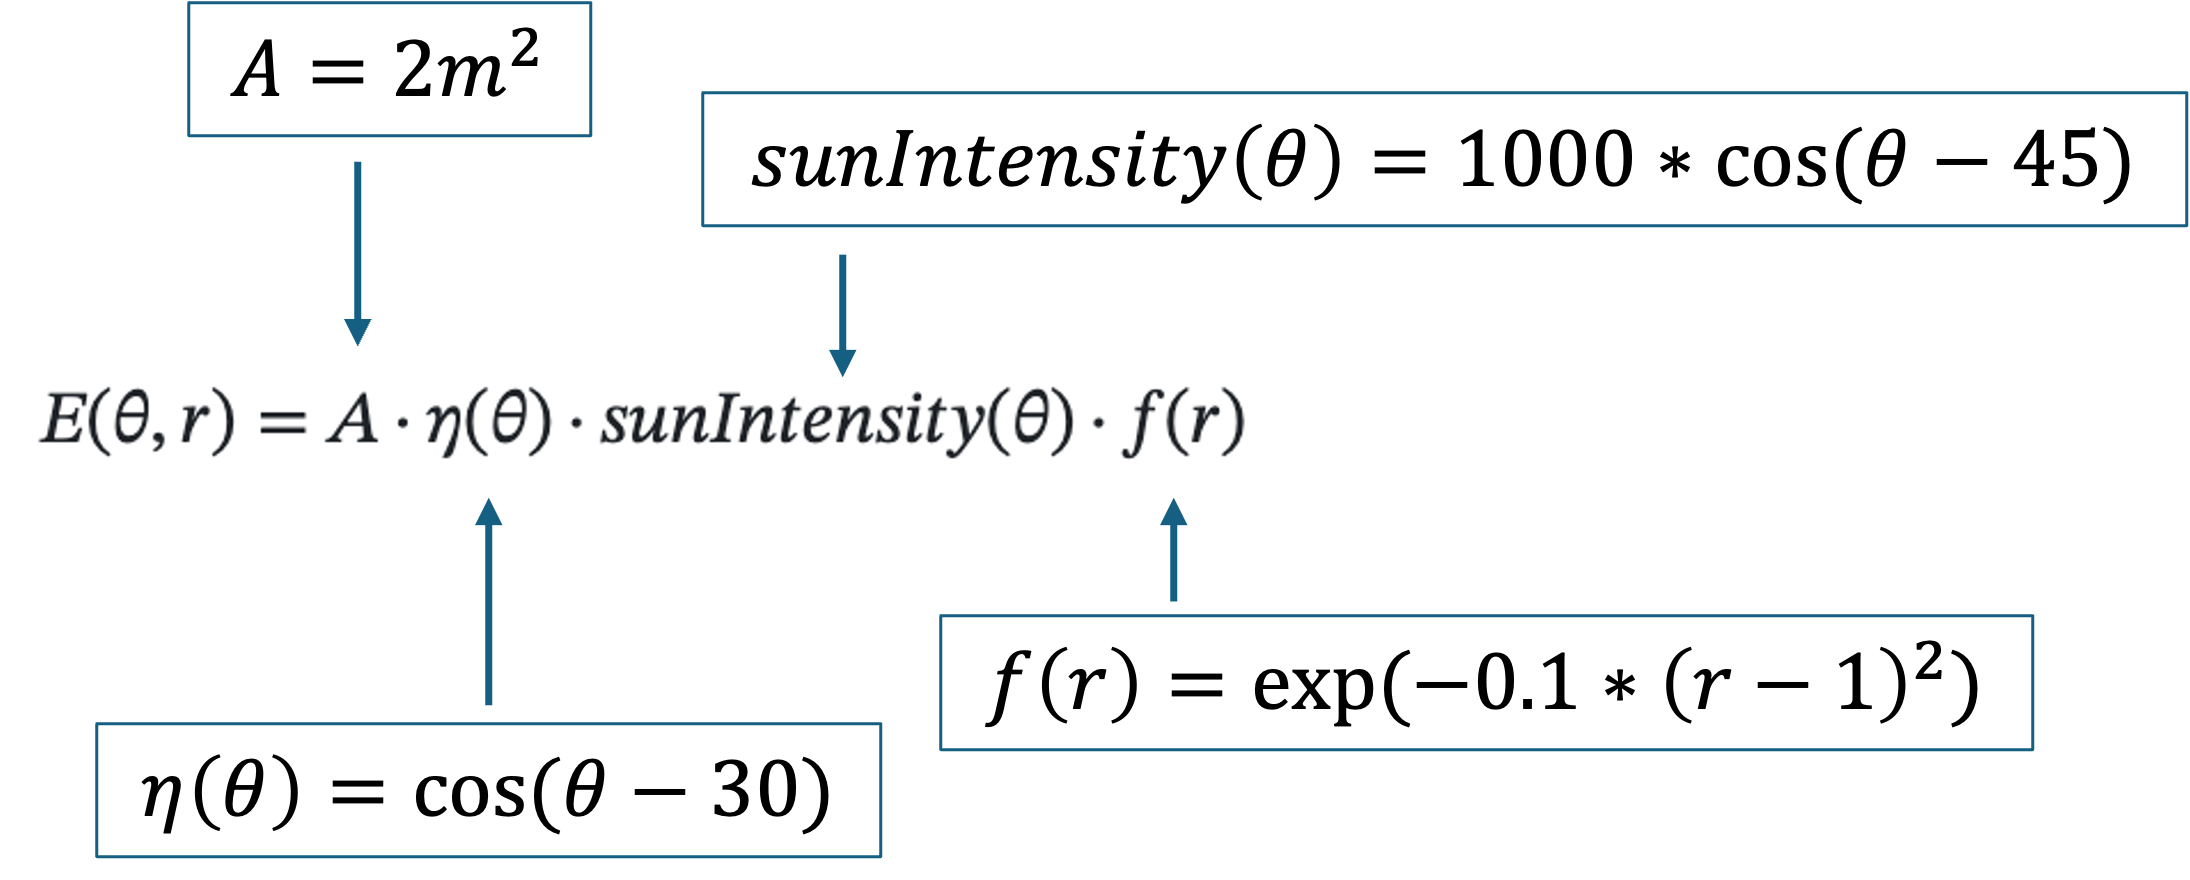

Note: The solver uses radian values instead of degrees. Multiplying inside the cosine function with pi/180 convert the theta values from degrees to radians.

% Step 1: Define 'A' (the fixed panel area) as 2m^2
    A = 2;

% Step 2: Define 'nu' (the angle efficiency) in terms of the optimization variable theta 
    nu = cos((theta - 30)*pi/180);

% Step 3: Define 'fr' (shape efficiency factor) in terms of the optimization variable r
    fr = exp(-0.1*(r - 1)^2);

% Step 4: Define 'Sun_Intensity' (variation in sunlight) in terms of the optimization variable theta
    Sun_Intensity = 1000*cos((theta - 45)*pi/180);

% Step 5: Define the Objective Function 'Energy' (Total Energy Output) in terms of A, nu, Sun_Intensity & fr which are in terms of theta and r
    Energy = A.*nu.*Sun_Intensity.*fr;

% Step 6: Create the Objective Function (Solar_Max.Objective)
    Solar_Max.Objective = Energy;

% Step 7: Set up the Initial Guess 
initial_guess.theta = 45;
initial_guess.r = 2;

% Step 8: Solve for the Maximum Energy Output and find the optimal Aspect ratio & Tilt angle 
[ solution, maxE ] = solve(Solar_Max,initial_guess);


Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


### Objective 3: Output the Results

**Plot E(θ, r)** to visualize the energy as a surface plot using `meshgrid` and [surf](https://www.mathworks.com/help/releases/R2026a/matlab/ref/surf.html). Plot the optimal tilt angle and aspect ratio, and corresponding energy output onto the grid; the absolute maximum of the surface plot should align with the optimal point. Finally, print the optimal tilt angle and aspect ratio, and the Maximum energy output.

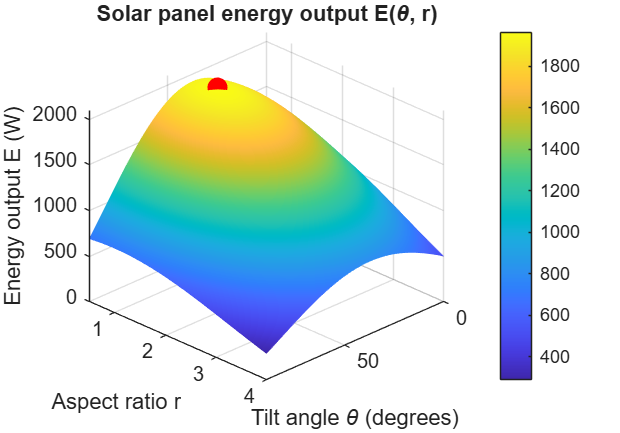

% Step 1: Create Grid Values for Tilt Angle and Aspect Ratio using meshgrid 

    % Set the lower bound to 0, the upper bound to 90 and the steps to 1
        theta_values = 0:1:90;
    % Set the lower bound to 0.5, the upper bound to 4 and the steps to 0.1
        r_values = 0.5:0.1:4;
    % Set up the meshgrid 
        [theta_grid, r_grid] = meshgrid(theta_values,r_values);

% Step 2: Create energy grid values that are dependent on the theta_values and r_values
    % Note: It's identical to 'Energy' the objective function
    energy_grid = 2.*(cos((theta_grid-30).*pi/180)).*(1000.*cos((theta_grid-45).*pi/180)).*(exp(-0.1.*(r_grid-1).^2));

% Step 3: Use figure command to position the size and location of the plot 
    figure("Position",[100,100, 1000, 700]);

% Step 4: Create the Surface Plot using the surf command
        surf(theta_grid,r_grid,energy_grid);
    % Add shading that illustrate the gradual change in energy output using shading and colorbar functions
        shading interp;
        colorbar;
    % Set Axis limits for the plot
        xlim([0 90]);
        ylim([0.5 4]);
        zlim([0 2100]);
    % Change the camera line of sight to gain a better view of the surface plot 
        view(135, 30);

% Step 5: Label the plot
xlabel("Tilt angle \theta (degrees)");
ylabel("Aspect ratio r");
zlabel("Energy output E (W)");
title("Solar panel energy output E(\theta, r)");
view(135, 30);

% Step 6: Plot the optimal point on the surface plot
    hold on; 
    plot3(solution.theta, solution.r, max_energy, "r.", "MarkerSize", 30);
    hold off;


% Step 7: Print Results
fprintf("Optimal Tilt Angle  : %.2f degrees\n", solution.theta);

Optimal Tilt Angle  : 37.50 degrees


fprintf("Optimal aspect ratio: %.2f\n", solution.r);

Optimal aspect ratio: 1.00


fprintf("Maximum energy      : %.2f W/m^2\n", maxE);

Maximum energy      : 1965.93 W/m^2


`Maximum energy      : 1965.93 W/m^2`

### Objective 4: Evaluate & Verify Results 

Evaluate the model to verify the results